### 通过本实验的练习，掌握了以下技能：

1.用freqz计算频率响应

2.用lsim计算微分方程

### 作业内容

#### 3.8a 创建向量a1、b1、a2、b2。

#### 系统1：y[n] - 0.8y[n-1] = x[n],  系统2：y[n] + 0.8y[n-1] = x[n]。

clc,clear,close all;
a1=[1 -0.8];
b1=[1];
a2=[1 0.8];
b2=[1];

#### 3.8b 用freqz计算频率响应，plot出abs(H)

使用feqz函数，freqz(b,a,N,'whole')

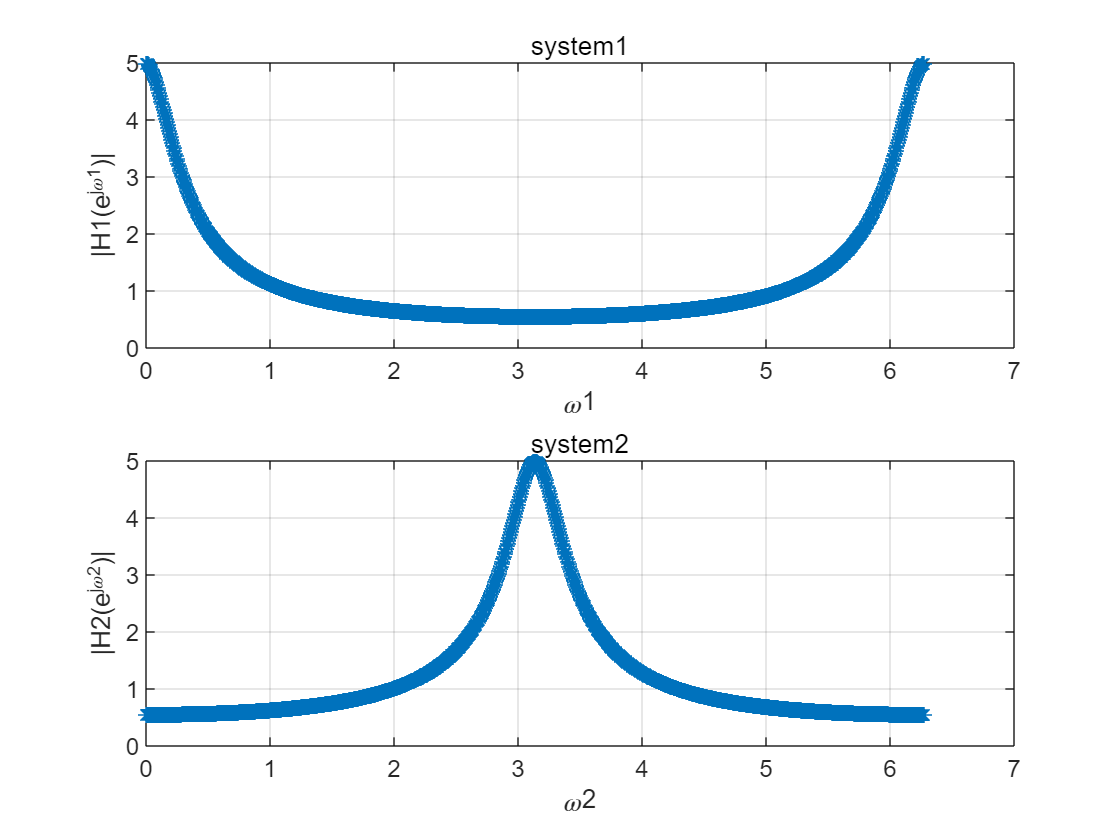

%计算频率响应
[H1,omega1]=freqz(b1,a1,1024,'whole');
[H2,omega2]=freqz(b2,a2,1024,'whole');
%画出H的模的图像
figure;
subplot(2,1,1),plot(omega1,abs(H1),'*-');
xlabel('\omega1'),ylabel('|H1(e^{j\omega1})|'),grid,title('system1');
subplot(2,1,2),plot(omega2,abs(H2),'*-');
xlabel('\omega2'),ylabel('|H2(e^{j\omega2})|'),grid,title('system2');

根据图像观察可得，系统1为低通滤波器，系统2为高通滤波器。

#### 3.8c 以omegak为横坐标，绘制系数a_x图像。

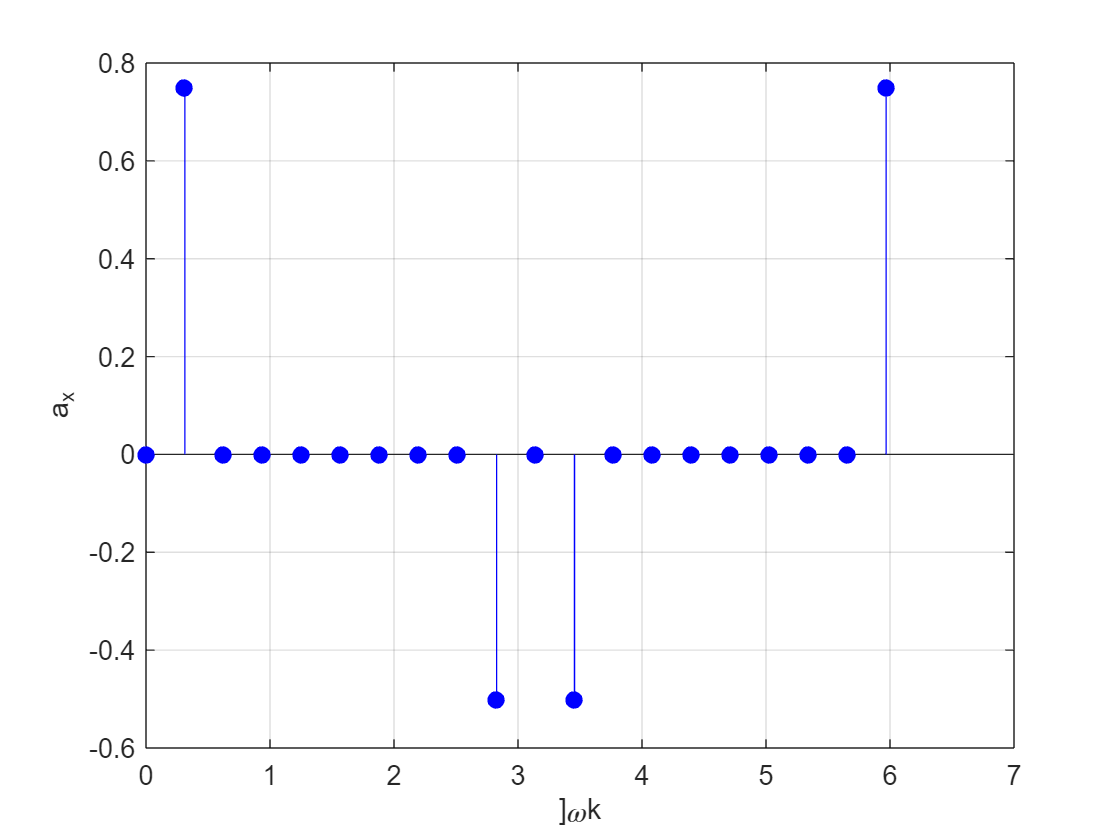

k=0:19;
omegak=k*pi/10;
a_x=[0 0.75 zeros(1,7) -0.5 0 -0.5 zeros(1,7) 0.75];
figure;
stem(omegak,a_x,'b','filled'),xlabel(']\omegak'),ylabel('a_x'),grid,xlim([0 7]);

根据图像观察可得，低频成分被放大，高频成分被衰减。

#### 3.8d 用ifft从a_x得到x，并扩展至[-20 99]

调用ifft函数，x=ifft(a_x)

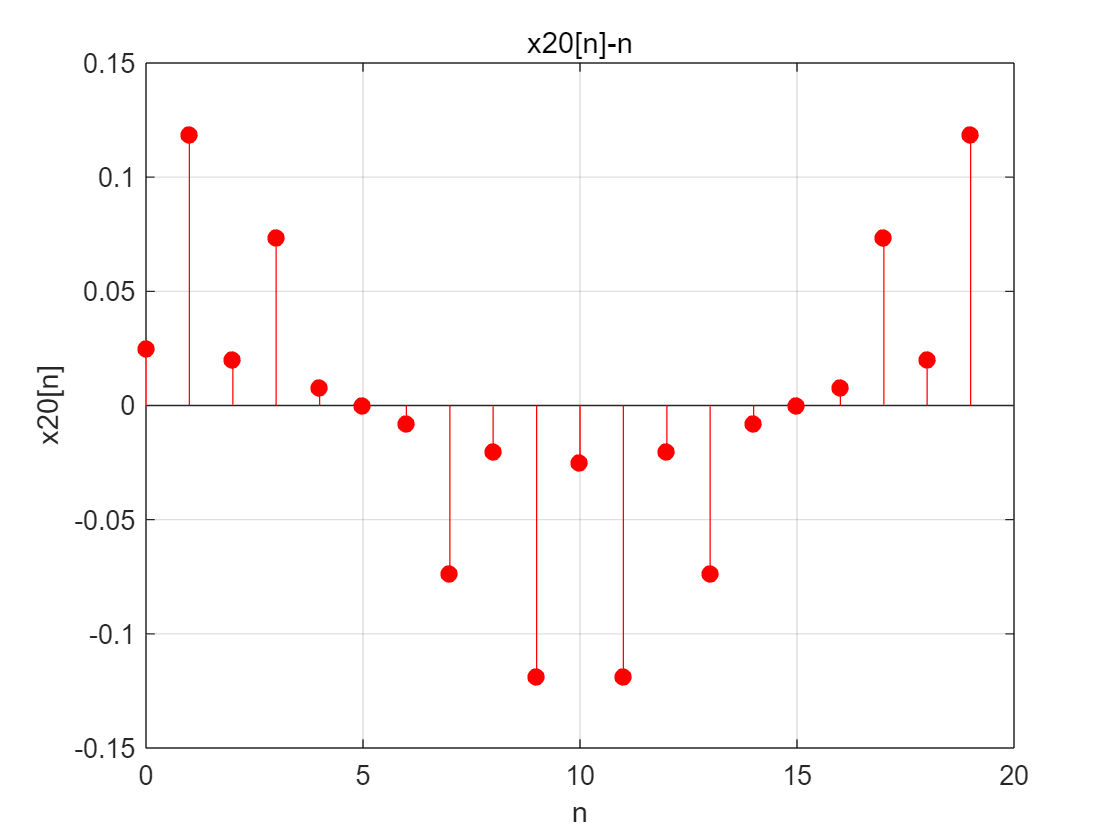

x_20=ifft(a_x);
n=-20:99;
figure;
stem(k,x_20,'r','filled'),xlabel('n'),ylabel('x20[n]'),grid,title('x20[n]-n');

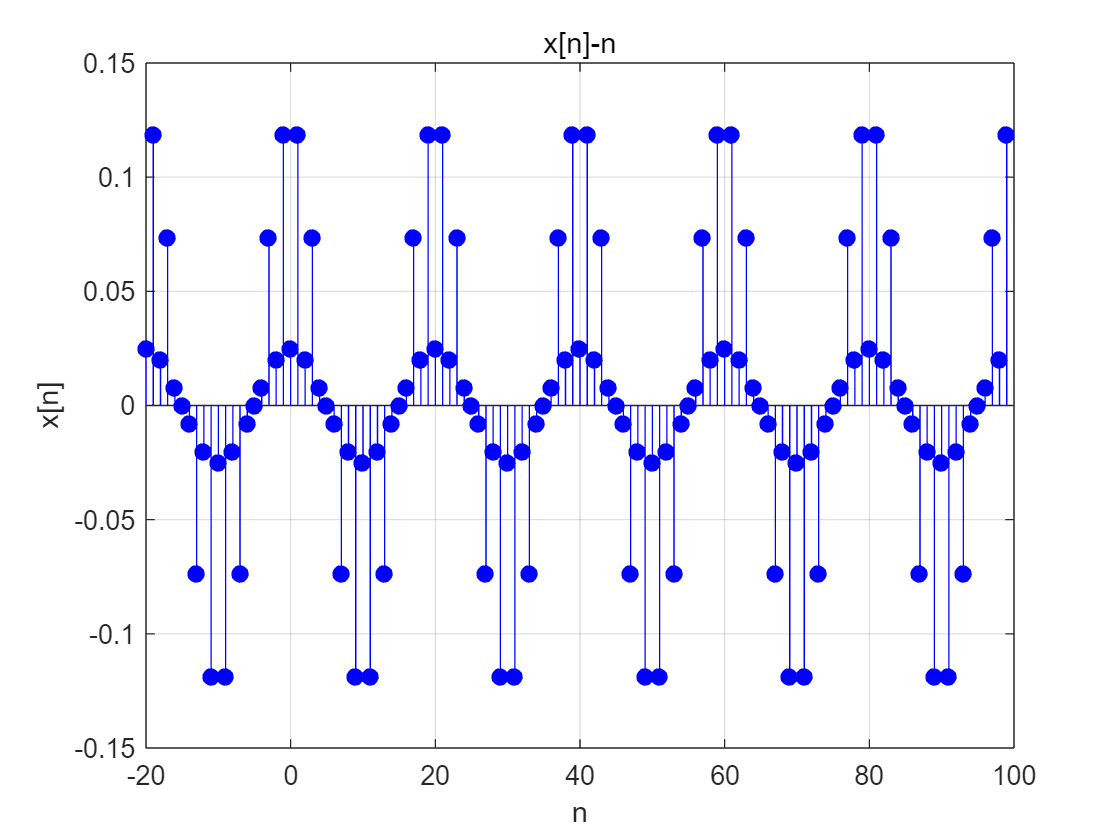

figure;
stem(n,[x_20 x_20 x_20 x_20 x_20 x_20],'b','filled'),xlabel('n'),ylabel('x[n]'),grid,title('x[n]-n');

#### 3.8e 用filter函数计算系统1，2的输出y1，y2。作图比较哪个系统输出包含更多高频能量，哪个包含更多低频能量。

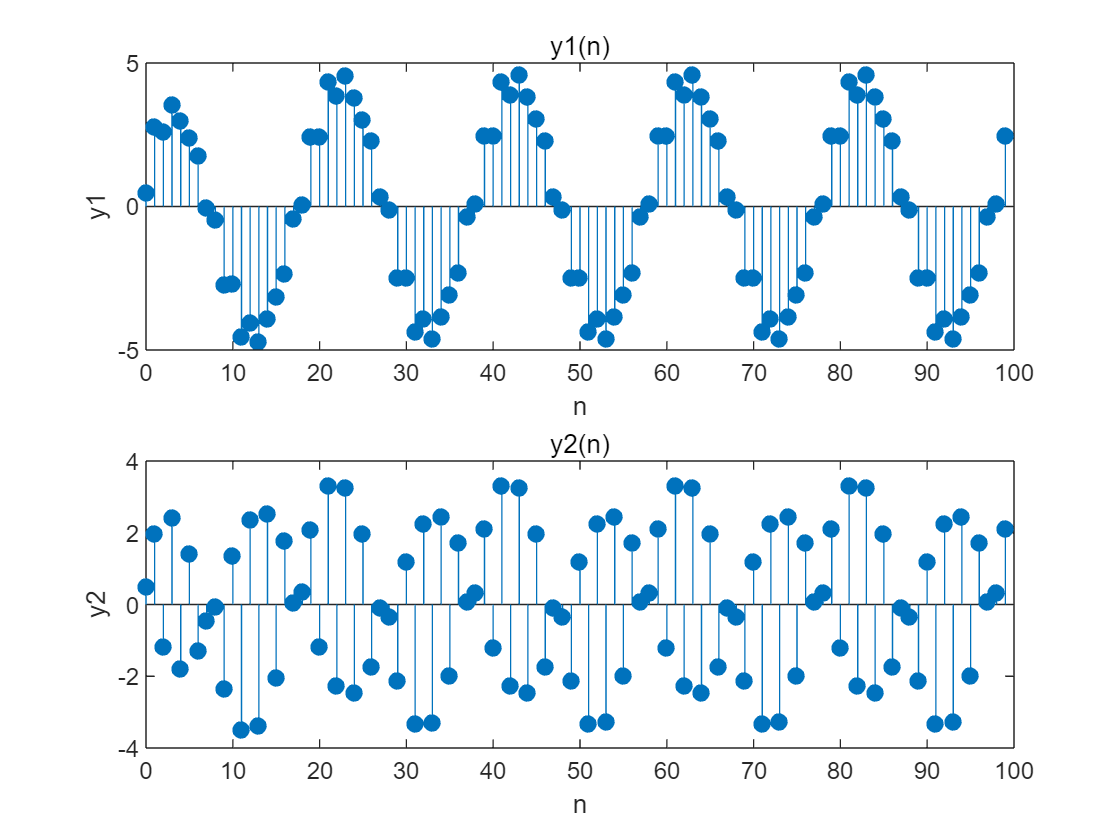

clc,clear,close all;
%前几问的参数
a1=[1 -0.8];
a2=[1 0.8];
b1=1;b2=1;
ak=[0 0.75 zeros(1,7) -0.5 0 -0.5 zeros(1,7) 0.75];
wk=linspace(0,2*pi,20);
%设置题目所需参数
n=0:99;
x0=20.*ifft(ak);%计算一个周期内的x
x=[x0 x0 x0 x0 x0];
y1=filter(b1,a1,x);
y2=filter(b2,a2,x);
figure;
subplot(2,1,1);
stem(n,y1,"filled");
xlabel('n');ylabel('y1');title('y1(n)');
subplot(2,1,2);
stem(n,y2,"filled");
xlabel('n');ylabel('y2');title('y2(n)');

如图所示，y2随n变化更快，估y2包含更多高频能量，y1包含更多低频能量

#### 3.8f 用 fft 函数计算 0-19 范围内 y1,y2 的傅里叶级数并画图，观察级数在频域的分布与e问的结论是否相同。

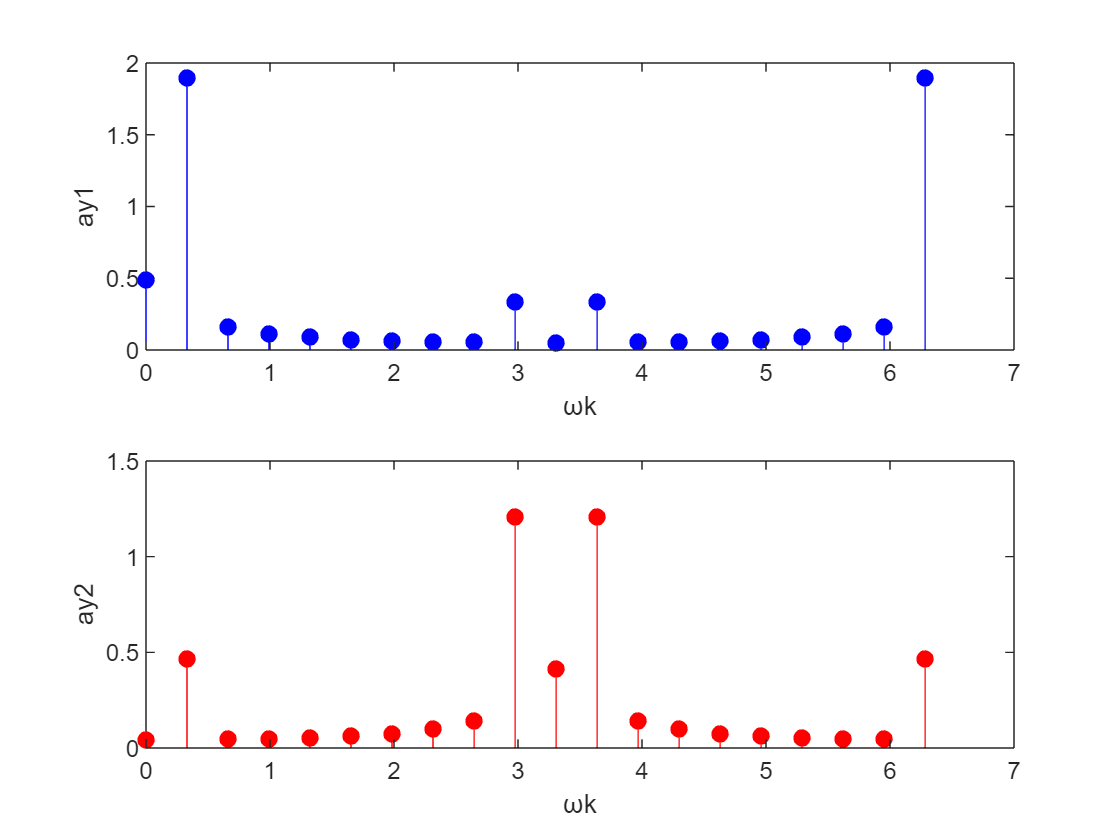

y1_20=y1(1:20);
y2_20=y2(1:20);
a_y1=1/20.*fft(y1_20);
a_y2=1/20.*fft(y2_20);
figure;
subplot(2,1,1);
stem(wk,abs(a_y1),'b','filled');
xlabel('ωk');
ylabel('ay1');
subplot(2,1,2);
stem(wk,abs(a_y2),'r','filled');
xlabel('ωk');
ylabel('ay2');

a_y1取值集中在2kpi处，a_y2取值集中在kpi处，说明y1低频，y2高频，与e问结论相符。

#### 课堂参与证明：

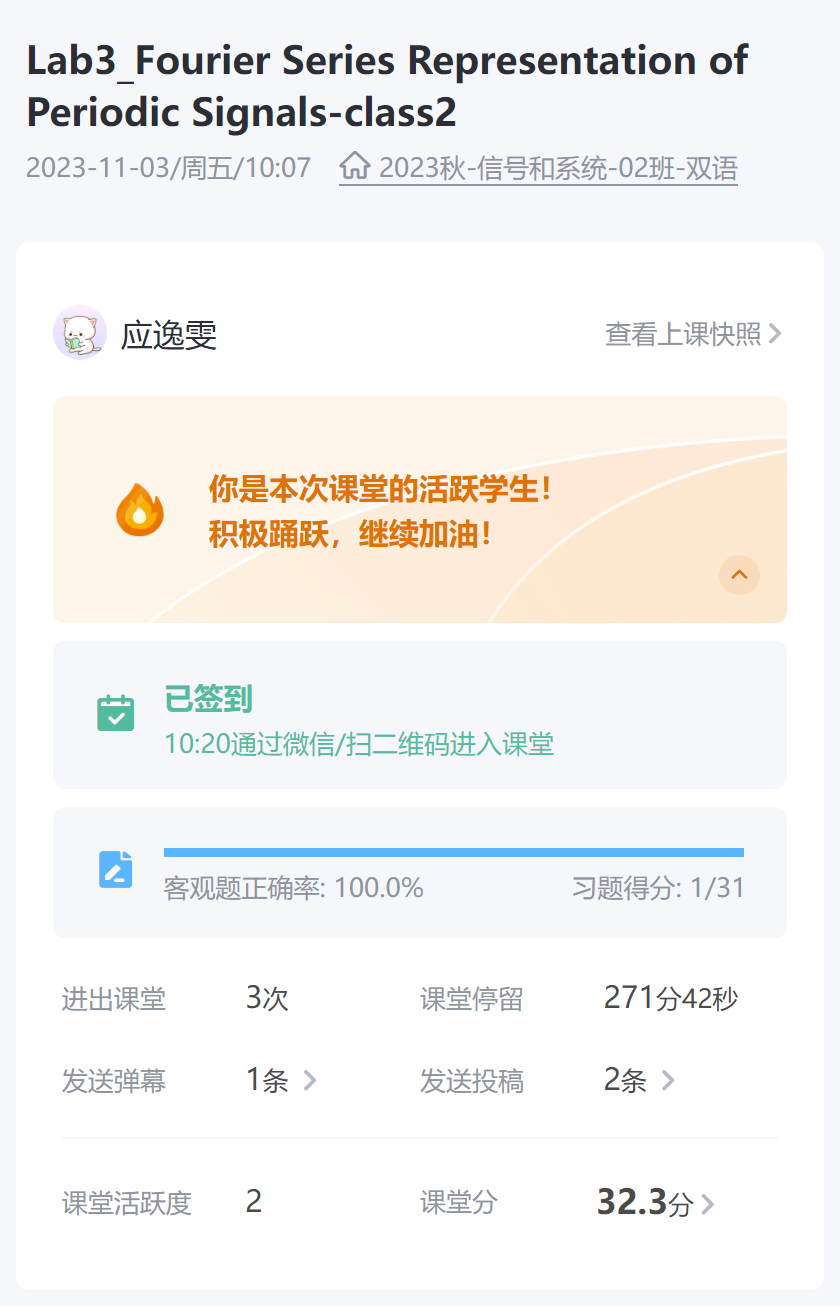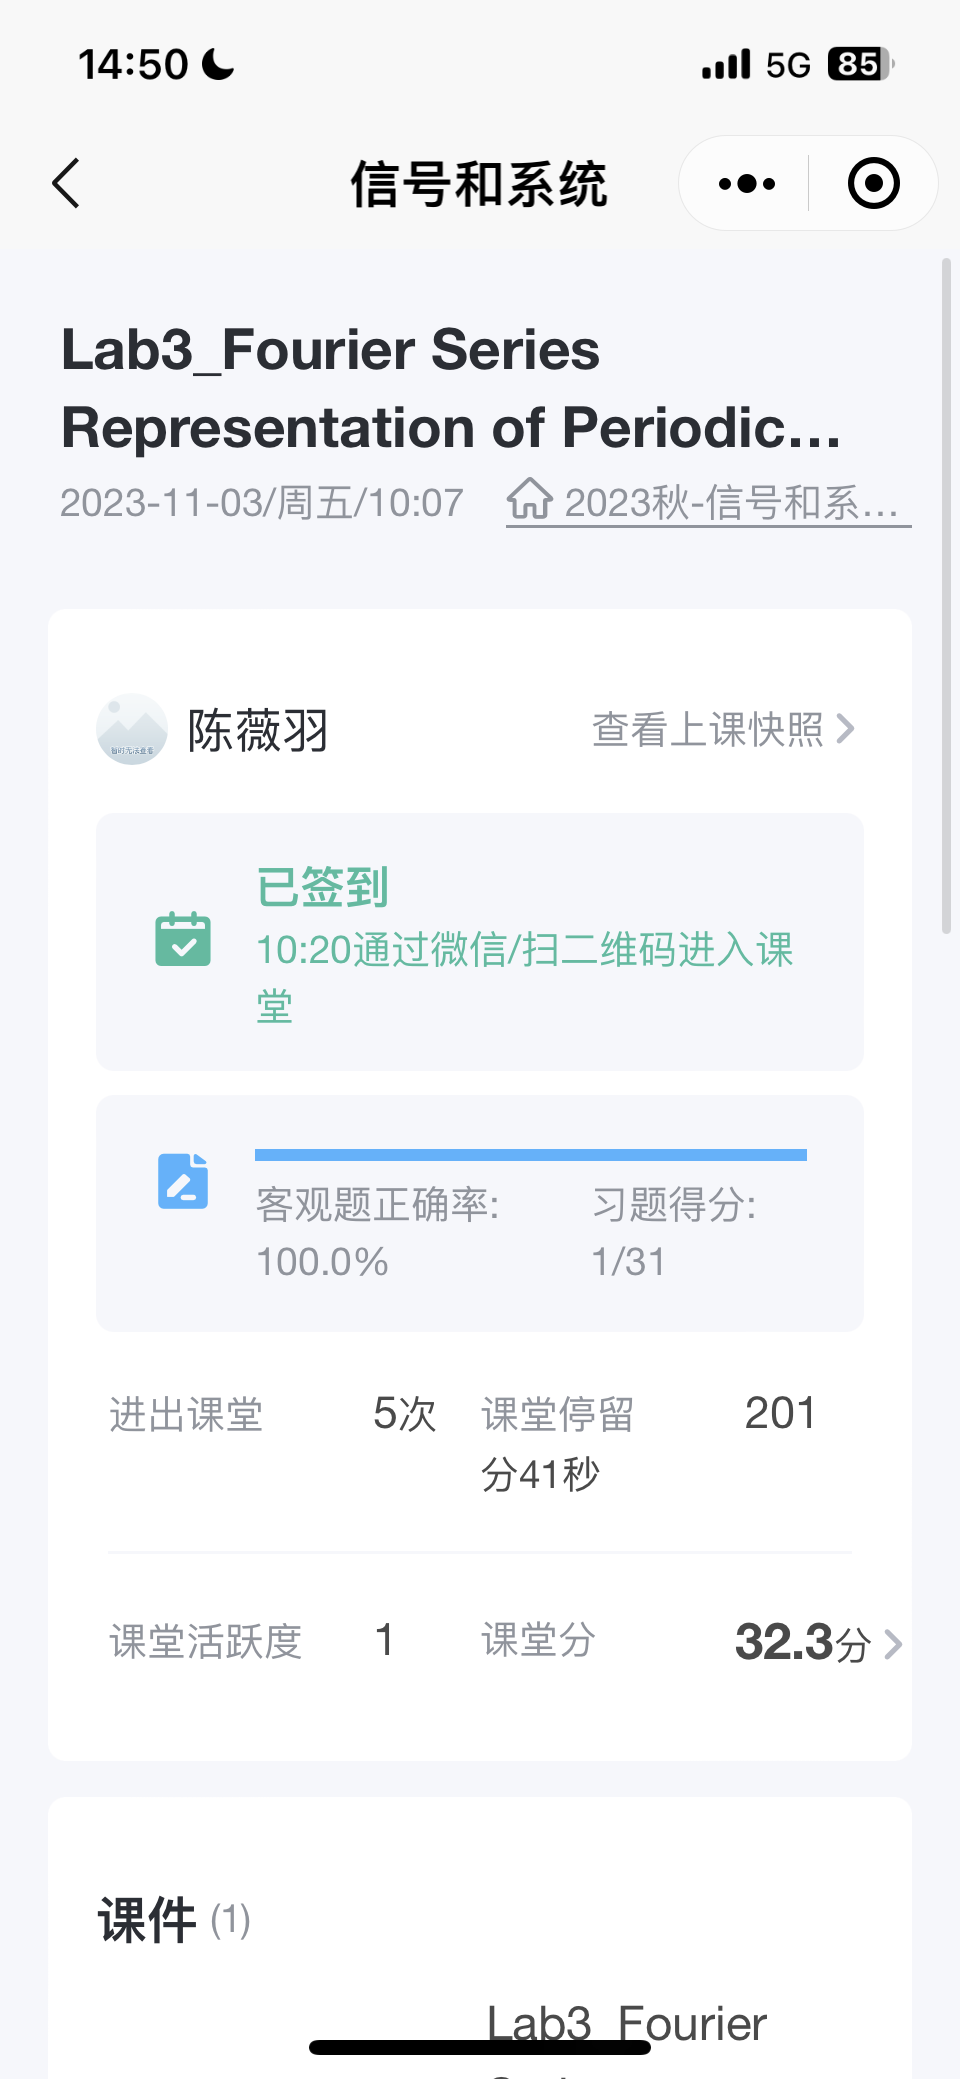

#### 自我评分：

应逸雯：10/10

陈薇羽：10/10